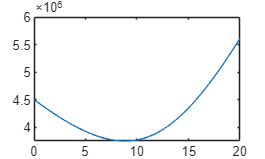

w  = 0:0.01:20;
fw = (3*sqrt(w.^2 - 24*w + 225)...
    + w)*10^5;
plot(w,fw)

% Initial guess
w = 12;
% Learning rate: Try these choices 3e-5 and 6e-5
eta = 0.5e-5;
numIteration = 50;
for i = 1:numIteration
    dfdw = (3*(2*w - 24)/(2*sqrt(w.^2 ...
        - 24*w + 225)) + 1)*10^5;
    w = w - eta*dfdw;
    %disp(w)
end

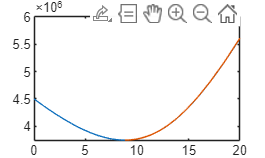


numIteration = 500;
w = zeros(numIteration,1);
w(1) = 20;
fw = zeros(numIteration,1);
fw(1) = (3*sqrt(w(1)^2 - 24*w(1) + 225)...
    + w(1))*10^5;
for i = 2:numIteration
    dfdw = (3*(2*w(i-1) - 24)/(2*sqrt(w(i-1)^2 ...
        - 24*w(i-1) + 225)) + 1)*10^5;
    w(i) = w(i-1) - eta*dfdw;
    fw(i) = (3*sqrt(w(i)^2 - 24*w(i) + 225)...
    + w(i))*10^5;
    %disp(w(i))
end
hold on
plot(w,fw)